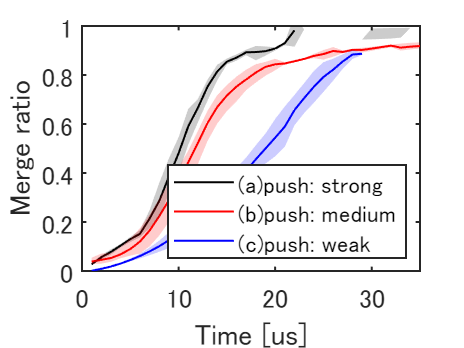

% clearvars -except fitrate1
%グループ分けした合体速度とシート傾きの比較
pathname.ts3u=getenv('ts3u_path');%old-koalaのts-3uまでのパス
pathname.fourier=getenv('fourier_path');%md0までのpath
pathname.NIFS=getenv('NIFS_path');%resultsまでのpath

DOCID='1wG5fBaiQ7-jOzOI-2pkPAeV6SDiHc_LrOdcbWlvhHBw';
T=getTS6log(DOCID);% ログのテーブルを取得

% IDXlist=[2911 2926 2931] %[2911 2927 2933 2948 2943]
% start=460;
% frame=50;
% elapsedtime=1:frame;
% trange=[1:frame]+start;
% figure
% for i=1:3
%     IDX=IDXlist(i)
%     [fitrate(:,i),merge_ind(1,i)] = fitratecalc(T, IDX, pathname,start,frame);
%     plotrange=frame-merge_ind(1,i)+1;
%     plot(elapsedtime(1:plotrange),fitrate(merge_ind(1,i):end,i),'-o')
%     hold on
% end
% hold off
% legend('No Cr','Cr 454 us','Cr 450 us','Location','southeast')
% ylim([0 1])
% xlim([0 30])
% ylabel('Merging ratio','FontSize',13)
% xlabel('Time [us]')
% ha1 = gca;
% ha1.LineWidth = 1;
% ha1.FontSize=13;
start=460;
frame=50;
elapsedtime=1:frame;
trange=[1:frame]+start;

IDXlist=[2911:2913 2925 2926 2927 2931 2933];
tstartlist=[472 472 472 477 477 477 482 482];
tendlist=[482 482 482 487 487 487 500 500];
tstartlist=tstartlist-start;
tendlist=tendlist-start;

fitrate=zeros(frame,numel(IDXlist));
merge_ind=zeros(1,numel(IDXlist));
plotrange=merge_ind;
p=zeros(2,frame,numel(IDXlist));
for i=1:numel(IDXlist)
    IDX=IDXlist(i);
    tstart=tstartlist(i);
    tend=tendlist(i);
    [fitrate(:,i),merge_ind(1,i)] = fitratecalc(T, IDX, pathname,start,frame);
    plotrange(1,i)=frame-merge_ind(1,i)+1;
    p(:,:,i)=cal_diff(T, IDX, pathname, tstart, tend,start,frame);
    p(:,1:tstart-1,i)=NaN;
    p(:,tend+1:frame,i)=NaN;
end

p(1,:,:)=p(1,:,:).*180./pi;

a_frame=frame-max(merge_ind(1,1:3));
afit=zeros(a_frame+1,3);
aslope=afit;
for i=1:3
    afit(:,i)=fitrate(merge_ind(1,i):merge_ind(1,i)+a_frame,i);
    aslope(:,i)=p(1,merge_ind(1,i):merge_ind(1,i)+a_frame,i);
end
arange=1:(a_frame+1);

b_frame=frame-max(merge_ind(1,4:6));
bfit=zeros(b_frame+1,3);
bslope=bfit;
for i=4:6
    bfit(:,i-3)=fitrate(merge_ind(1,i):merge_ind(1,i)+b_frame,i);
    bslope(:,i-3)=p(1,merge_ind(1,i):merge_ind(1,i)+b_frame,i);
end
brange=1:(b_frame+1);

c_frame=frame-max(merge_ind(1,7:8));
cfit=zeros(c_frame+1,2);
cslope=cfit;
for i=7:8
    cfit(:,i-6)=fitrate(merge_ind(1,i):merge_ind(1,i)+c_frame,i);
    cslope(:,i-6)=p(1,merge_ind(1,i):merge_ind(1,i)+c_frame,i);
end
crange=1:(c_frame+1);

figure
plot(arange,mean(afit(:,1:3),2),'k-','LineWidth',1)
hold on
plot(brange,mean(bfit(:,1:3),2),'r-','LineWidth',1)
plot(crange,mean(cfit(:,1:2),2),'b-','LineWidth',1)
 ar1 = area(arange,[max(afit(:,1:3),[],2), min(afit(:,1:3),[],2)-max(afit(:,1:3),[],2)]);
set(ar1(1),'FaceColor','None','LineStyle','None')
set(ar1(2),'FaceColor','k','FaceAlpha',0.2,'LineStyle','None')
 ar2 = area(brange,[max(bfit(:,1:3),[],2), min(bfit(:,1:3),[],2)-max(bfit(:,1:3),[],2)]);
set(ar2(1),'FaceColor','None','LineStyle','None')
set(ar2(2),'FaceColor','r','FaceAlpha',0.2,'LineStyle','None')
 ar3 = area(crange,[max(cfit(:,1:2),[],2), min(cfit(:,1:2),[],2)-max(cfit(:,1:2),[],2)]);
set(ar3(1),'FaceColor','None','LineStyle','None')
set(ar3(2),'FaceColor','b','FaceAlpha',0.2,'LineStyle','None')
hold off
%grid on
ylabel('Merge ratio')
xlabel('Time [us]')
xlim([0 35])
ylim([0 1])
%legend('No Cr','Cr 454 us','Cr 450 us','Location','southeast')
legend('(a)push: strong','(b)push: medium','(c)push: weak','Location','southeast')
ha1 = gca;
ha1.LineWidth = 1;
ha1.FontSize=13;

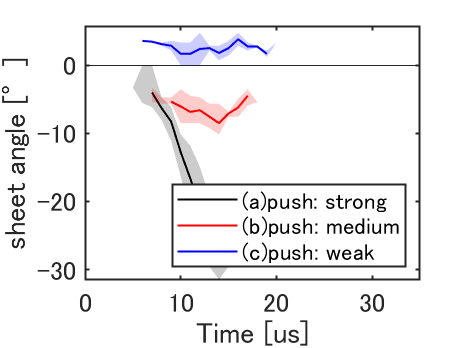


figure
plot(arange,mean(aslope(:,1:3),2),'k-','LineWidth',1)
hold on
plot(brange,mean(bslope(:,1:3),2),'r-','LineWidth',1)
plot(crange,mean(cslope(:,1:2),2),'b-','LineWidth',1)
 ar1 = area(arange,[max(aslope(:,1:3),[],2), min(aslope(:,1:3),[],2)-max(aslope(:,1:3),[],2)]);
set(ar1(1),'FaceColor','None','LineStyle','None')
set(ar1(2),'FaceColor','k','FaceAlpha',0.2,'LineStyle','None')
 ar2 = area(brange,[max(bslope(:,1:3),[],2), min(bslope(:,1:3),[],2)-max(bslope(:,1:3),[],2)]);
set(ar2(1),'FaceColor','None','LineStyle','None')
set(ar2(2),'FaceColor','r','FaceAlpha',0.2,'LineStyle','None')
 ar3 = area(crange,[max(cslope(:,1:2),[],2), min(cslope(:,1:2),[],2)-max(cslope(:,1:2),[],2)]);
set(ar3(1),'FaceColor','None','LineStyle','None')
set(ar3(2),'FaceColor','b','FaceAlpha',0.2,'LineStyle','None')
hold off
%grid on
ylabel('sheet angle [°]')
xlabel('Time [us]')
xlim([0 35])
ylim([-0.55 0.1].*180./pi)
%legend('No Cr','Cr 454 us','Cr 450 us','Location','southeast')
legend('(a)push: strong','(b)push: medium','(c)push: weak','Location','southeast')
ha2 = gca;
ha2.LineWidth = 1;
ha2.FontSize=13;



% figure
% %plot(repmat([1:50]+465,9,1)',fitrate)
% %h=plot(repmat([1:frame]+start,3,1)',[mean(fitrate(:,1:3),2) mean(fitrate(:,4:6),2) mean(fitrate(:,7:8),2)]);
% plot(trange,mean(fitrate(:,1:3),2),'k-','LineWidth',1)
% hold on
% plot(trange,mean(fitrate(:,4:6),2),'r-','LineWidth',1)
% plot(trange,mean(fitrate(:,7:8),2),'b-','LineWidth',1)
%  ar1 = area(trange,[max(fitrate(:,1:3),[],2), min(fitrate(:,1:3),[],2)-max(fitrate(:,1:3),[],2)]);
% % Appearances
% %set(h,'Color',('r','b','c'))
% set(ar1(1),'FaceColor','None','LineStyle','None')
% set(ar1(2),'FaceColor','k','FaceAlpha',0.2,'LineStyle','None')
%  ar2 = area(trange,[max(fitrate(:,4:6),[],2), min(fitrate(:,4:6),[],2)-max(fitrate(:,4:6),[],2)]);
% % Appearances
% %set(h,'Color',('r','b','c'))
% set(ar2(1),'FaceColor','None','LineStyle','None')
% set(ar2(2),'FaceColor','r','FaceAlpha',0.2,'LineStyle','None')
%  ar3 = area(trange,[max(fitrate(:,7:8),[],2), min(fitrate(:,7:8),[],2)-max(fitrate(:,7:8),[],2)]);
% % Appearances
% %set(h,'Color',('r','b','c'))
% set(ar3(1),'FaceColor','None','LineStyle','None')
% set(ar3(2),'FaceColor','b','FaceAlpha',0.2,'LineStyle','None')
% %  ar4 = area(([1:frame]+start),[max(fitrate(:,9:12),[],2), min(fitrate(:,9:12),[],2)-max(fitrate(:,9:12),[],2)]);
% % % Appearances
% % %set(h,'Color',('r','b','c'))
% % set(ar4(1),'FaceColor','None','LineStyle','None')
% % set(ar4(2),'FaceColor',[1 0.8 0],'FaceAlpha',0.2,'LineStyle','None')
% %  ar5 = area(([1:frame]+start),[max(fitrate(:,13:15),[],2), min(fitrate(:,13:15),[],2)-max(fitrate(:,13:15),[],2)]);
% % % Appearances
% % %set(h,'Color',('r','b','c'))
% % set(ar5(1),'FaceColor','None','LineStyle','None')
% % set(ar5(2),'FaceColor',[0.2 1.0 0],'FaceAlpha',0.2,'LineStyle','None')
% hold off
% grid on
% % 
% ylabel('Merge ratio')
% xlabel('Time [us]')
% ylim([0 1])
% legend('No Cr','Cr 454 us','Cr 450 us','Location','southeast')
% ha1 = gca;
% ha1.LineWidth = 1;
% ha1.FontSize=13;


function [fitrate, merge_ind] = fitratecalc(T, IDX, pathname,start,frame)
date=T.date(IDX);
shot=T.shot(IDX);
TF_shot=T.TFoffset(IDX);
d_tacq=T.d_tacq(IDX);
d_tacqTF=T.TFdtacq(IDX);
offset_TF=isfinite(TF_shot);
Cr=T.Crowbar_us_(IDX);
if isnan(Cr)
    Cr=num2str('-');
end
CB=T.CB1_kV_(IDX);
%start=T.Period_StartTime_(IDX);
if isnan(T.EF_A_(IDX))
    i_EF=150;
else  
    i_EF=T.EF_A_(IDX);
end
% %rgwデータの読み込み->coil current plot用
% filepath.rgw=strcat(pathname.ts3u, '/', string(date),'/' ...
%     ,string(date),num2str(shot,'%03i'),'.rgw');
% 
% if exist(filepath.rgw)~=0
% rgwdata = importfile(filepath.rgw);
% rgwdata.ch6=rgwdata.ch6*(65.7146)*12;
% rgwdata.ch7=rgwdata.ch7*(-57.6030)*3;
% rgwdata.ch8=rgwdata.ch8*(-187.170)*3-50;
% %各ショットのTF,PF1,PF2のcoil current
% plot(repmat([0:0.1:0.1*10000],3,1)',rgwdata{2:end,:})
% legend('TF','PF1','PF2')
% ylabel('coil current [kA]')
% ylim([-250 150])
% xlim([300 550])
% title(strcat('IDX',num2str(IDX),': Cr',num2str(T.Crowbar_us_(IDX))))
% hold off
% end

[B_z,r_probe,z_probe,ch_dist,data,data_raw,shot_num]= get_B_z(date,TF_shot,shot,offset_TF,i_EF,pathname.ts3u);
B_z = B_z([2,3,4,6,7,8],2:end,:);
data = data([2,3,4,6,7,8],2:end,:);
z_probe = z_probe(2:end);
ch_dist = ch_dist([2,3,4,6,7,8],2:end);
r_probe = r_probe([2,3,4,6,7,8]);

mesh_z=100;
mesh_r=100;

z_space = linspace(z_probe(1),z_probe(end),mesh_z);
r_space = linspace(r_probe(1),r_probe(end),mesh_r);
[psi_mesh_z,psi_mesh_r] = meshgrid(z_space,r_space);
for i=1:frame
    psi  = get_psi(B_z,r_probe,i+start);
    psi_store(:,:,i)= griddata(z_probe,r_probe,psi,psi_mesh_z,psi_mesh_r,'cubic');
end

[max_psi,max_psi_r]=max(psi_store,[],1); %各時間、各列(z)ごとのpsiの最大値
max_psi=squeeze(max_psi);
psi_pr=zeros(3,frame);
%plot(max_psi)
for i=1:frame
    r_ind=max_psi_r(:,:,i);
    max_psi_ind=find(islocalmax(smooth(max_psi(:,i)),'MaxNumExtrema', 2));
    if numel(max_psi(min(max_psi_ind),i))==0
    psi_pr(1,i)=NaN;
    else
    psi_pr(1,i)=max_psi(min(max_psi_ind),i);
    end
    if numel(max_psi(max(max_psi_ind),i))==0
    psi_pr(2,i)=NaN;
    else
    psi_pr(2,i)=max_psi(max(max_psi_ind),i);
    end
    if numel(find(islocalmin(smooth(max_psi(:,i)),'MaxNumExtrema', 1)))==0
        psi_pr(3,i)=NaN;
    else
        min_psi_ind=islocalmin(smooth(max_psi(:,i)),'MaxNumExtrema', 1);
        xr=r_ind(min_psi_ind);
        if xr==1 || xr==mesh_r %r両端の場合は検知しない
            psi_pr(3,i)=NaN;
        else
        psi_pr(3,i)=max_psi(min_psi_ind,i);
        end
    end
    if max_psi(1,i)==max(max_psi(1:end/2,i))
        psi_pr(1,i)=NaN; %max_psi(1,i);
    end    
    if max_psi(end,i)==max(max_psi(end/2:end,i))
        psi_pr(2,i)=NaN; %max_psi(end,i);
    end
end
fitrate=psi_pr(3,:)./min(psi_pr(1:2,:),[],1);
merge_ind=find(fitrate>=0,1); %fitrateが初めて0以上となる点のindex
% %合体率のplot
% figure('Position',[700,350,350,300])
% plot(repmat([1:frame]+start,3,1)',psi_pr','--o')
% ylabel('Psi [Wb]')
% xlabel('Time [us]')
% ylim([0 inf])
% legend('Psi_{private1}','Psi_{private2}','Psi_{common}')
% title(strcat('IDX',num2str(IDX),', Cr',num2str(Cr),' us, CB',num2str(CB),' kV'))
% title(strcat('IDX',num2str(IDX),' CB:',num2str(T.CB1_kV_),' kV, Cr:',num2str(T.Crowbar_us_),' us'))
end

function p=cal_diff(T, IDX, pathname, tstart, tend,start,frame)
date=T.date(IDX);
if isnan(T.EF_A_(IDX))%%NaNでないことを確認（ログが空白だとNaNになる）
    i_EF=150;
else  %NaNなら150をとりあえず代入、記入されているときはその値を使う
    i_EF=T.EF_A_(IDX);
end
d_tacq=T.d_tacq(IDX);
d_tacqTF=T.TFdtacq(IDX);
n=50; %rz方向のメッシュ数

%trange = tstart:tend+1;
%tsize = tend-tstart+1;
tsize=frame;
trange=[1:frame]+start;

[grid2D, data2D] = pcbdata(date, d_tacq, d_tacqTF, trange, [], n,i_EF);

if isstruct(grid2D)==0 %もしdtacqデータがない場合次のloopへ(データがない場合NaNを返しているため)
    return
end

%%%midplaneとかO点、X点を探す
[psimid,mid]=min(data2D.psi,[],2);
[opoint,~]=islocalmin(psimid,1);
[xpoint,~]=islocalmax(psimid,1);
% [xp_psi,maxxp]=max(squeeze(psimid),[],1);
r_index=1:n;

%X点での勾配
p=zeros(2,tsize);

for i=1:tsize
    if sum(xpoint(:,:,i))>0   
        r_xind=r_index(xpoint(:,:,i));
        z_xind=mid(xpoint(:,:,i),:,i);
        if numel(r_xind)>1
            [~,I]=max(psimid(r_xind));
            r_xind=r_xind(I);
            z_xind=z_xind(I);
        end
        
        r_s=max(2,r_xind-5);
        r_n=min(n,r_xind+5);
        p(:,i)=polyfit(grid2D.rq(r_s:r_n,1),grid2D.zq(1,squeeze(mid(r_s:r_n,:,i))),1);

        if z_xind==1 || z_xind==n
            p(:,i)=NaN;
        end
    else
        p(:,i)=NaN;
    end   
end


% figure
% plot(tstart:tend,p(1,:),'ko-')
% xlim([tstart tend])
% xlabel('Time [us]')
% ylabel('current sheet slope')
% ylim([-0.55 0.1])
% ha3 = gca;
% ha3.LineWidth = 1;
% ha3.FontSize=13;
% Cr=T.Crowbar_us_(IDX);
% if isnan(Cr)
%     Cr=num2str('-');
% end
% CB=T.CB1_kV_(IDX);
% sgtitle(strcat('IDX',num2str(IDX),', Cr',num2str(Cr),' us, CB',num2str(CB),' kV'),'FontSize',12)
end